# Question 4

Read input file:

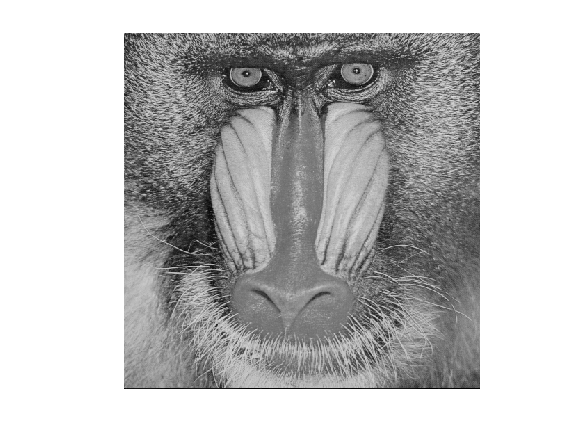

im = imread("/MATLAB Drive/images/mandrill.tif");
imshow(im)

Using Fast Fourier Tranform inbuilt function:

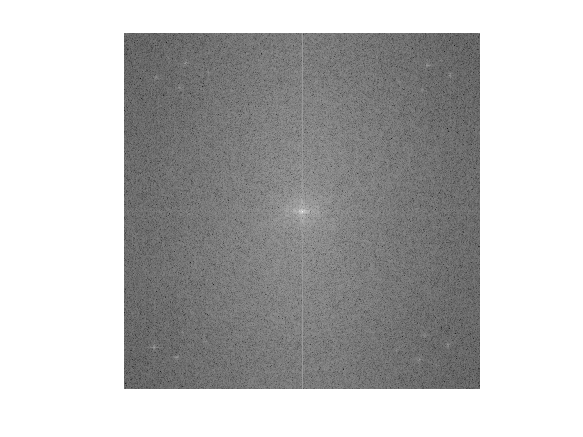

fim = fftshift(fft2(im));
imshow(mat2gray(log(1+abs(fim))))

## Butterworth Filter:

Creating low-pass filter for D = 100, n = 2, on our 512x512 image:

D = 100

D = 100

n = 2

n = 2

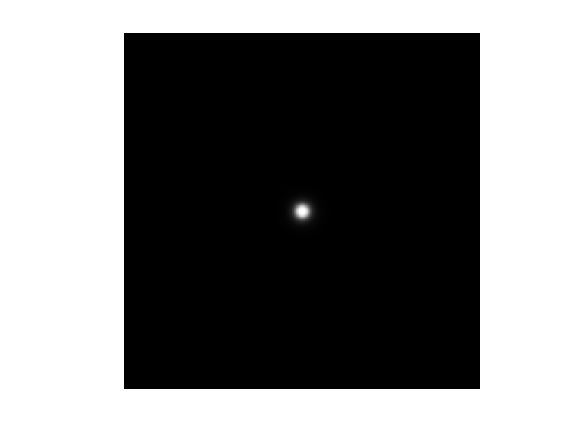

[x,y] = meshgrid(-256:255,-256:255);
bl = 1./(1+((x.^2+y.^2)/D).^n);
imshow(bl)

Applying and showing DFT after our low-pass Butterworth filter:

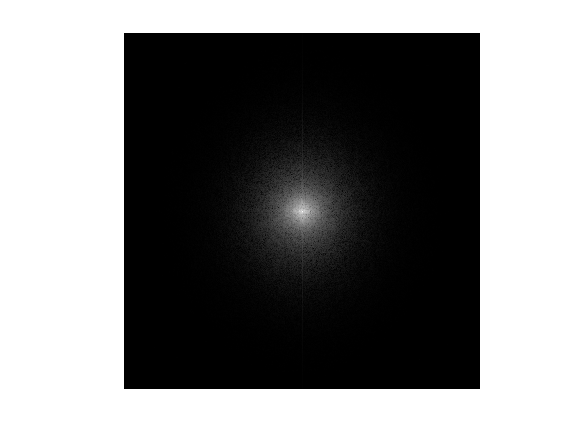

fimbl = fim.*bl;
imshow(mat2gray(log(1+abs(fimbl))))

Inversing the transform to get resulting filtered image:

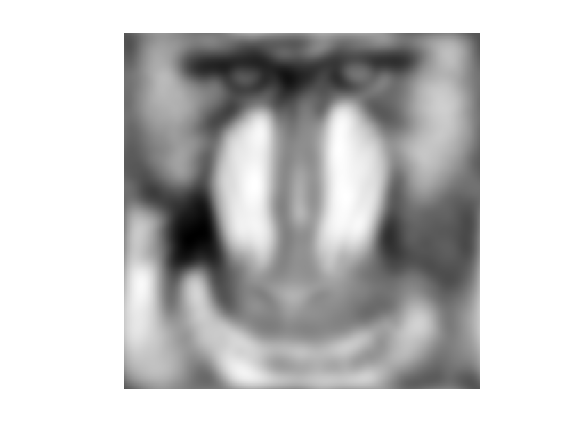

imshow(mat2gray(abs(ifft2(fimbl))))

Running a high pass version yields:

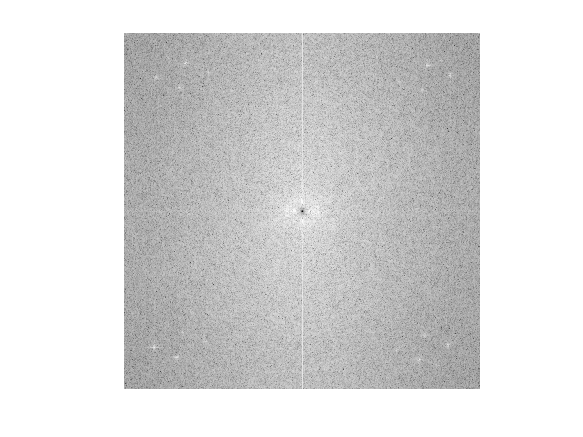

bh = 1 - 1./(1+((x.^2+y.^2)/D).^n);
fimbh = fim.*bh;
imshow(mat2gray(log(1+abs(fimbh))))

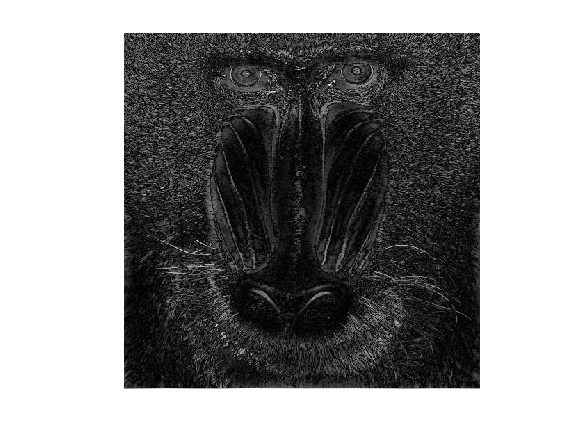

imshow(mat2gray(abs(ifft2(fimbh))))

## Gaussian Filter:

Create low-pass filter using fspecial function:

sigma = 20

sigma = 20

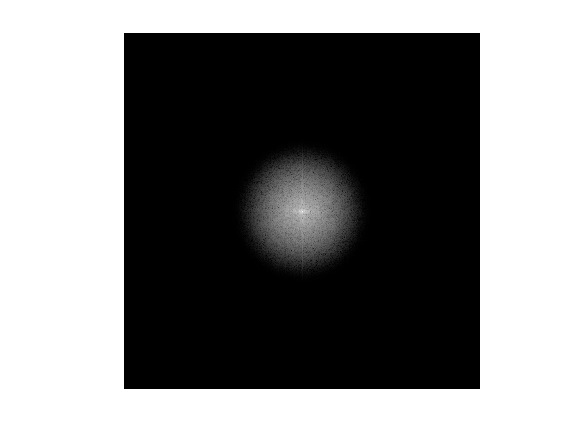

g=mat2gray(fspecial('gaussian',512,sigma));
fimg=fim.*g;
imshow(mat2gray(log(1+abs(fimg))))

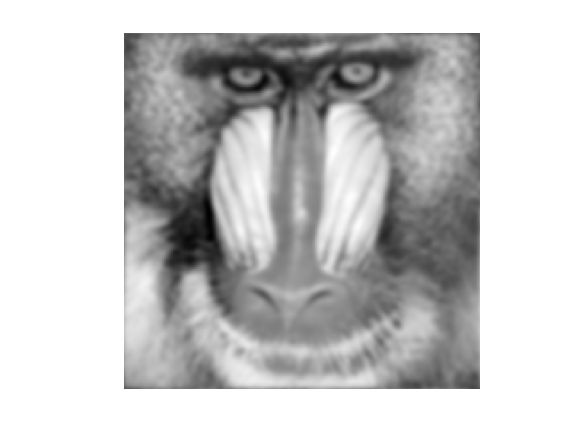

imshow(mat2gray(abs(ifft2(fimg))))

We can similarly make a high-pass Gaussian filter:

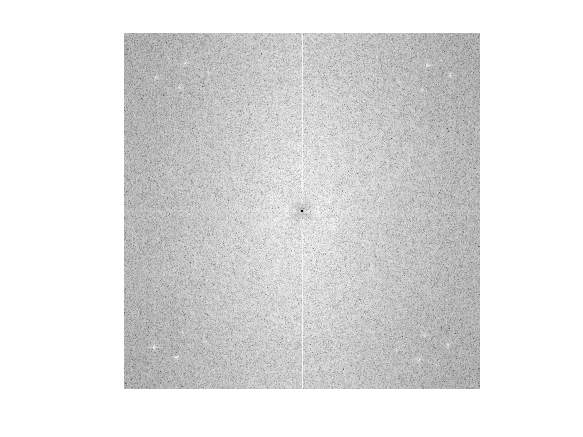

g2 = 1-g;
fimg2=fim.*g2;
imshow(mat2gray(log(1+abs(fimg2))))

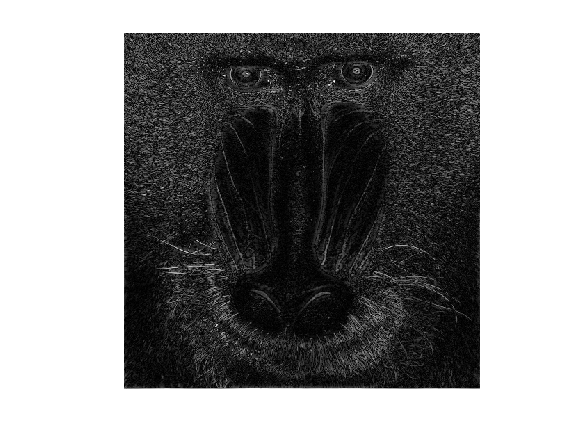

imshow(mat2gray(abs(ifft2(fimg2))))